Суммарный момент

clear 
clc

data = [
    0.0145, 0.0013, 0.0158;  % Mx
    0.0606, 0.0151, 0.0757;  % My
    0.0456, 0.0113, 0.0569;  % Mz
];

% Подписи осей
categories = {'Mx', 'My', 'Mz'};
series = {'момент от смещения ЦМ', 'момент от двигателей', 'Суммарный момент'};

% 3D столбчатая диаграмма
figure;
bar3(data, 0.3);  % 0.4 — это ширина столбика (от 0 до 1)

% Получить массив "детей" (столбцов)
h = get(gca, 'Children');

% Перебрать каждый бар (3 группы столбцов)
for k = 1:length(h)
    zdata = get(h(k), 'ZData');
    set(h(k), ...
        'CData', zdata, ...
        'FaceColor', 'interp');
end

set(gca, 'XTickLabel', series);
set(gca, 'YTick', 1:3, 'YTickLabel', categories);



view([-71.3565 11.8043])

zlabel('Н\cdot м');

exportgraphics(gcf, 'moments_chart.pdf', 'ContentType', 'vector', 'BackgroundColor', 'white');

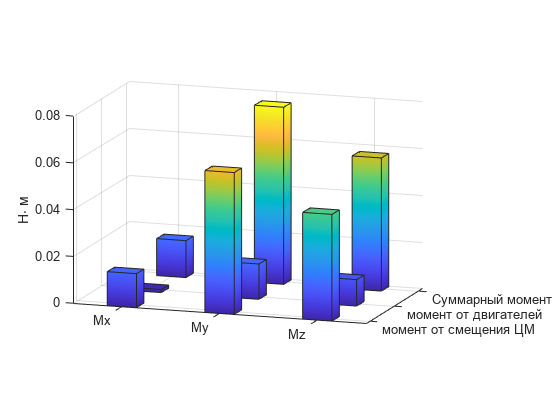



grid on;

Синусоидальный алгоритм

clear
clc

t = linspace(0,10,1000);
T = 4;
f = 2*pi/T;

phi1 = deg2rad(17)

phi1 = 0.2967


U = ((f^2)*phi1) / (f*T - sin(f*T))

U = 0.1165

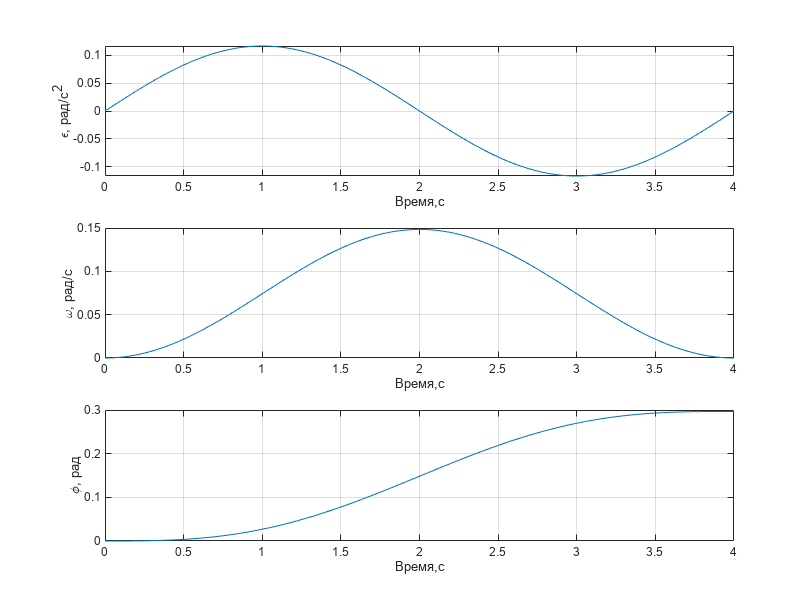



eps = U *  sin(f*t);
omeg = U/f*(1-cos(f*t));
phi = (U/f^2)*(f*t-sin(f*t));



figure('Units','normalized', 'Position',[0.1 0.1 0.6 0.8])
subplot(3,1,1);
plot(t, eps);
grid on
xlabel('Время,с');
ylabel("\epsilon, рад/с^2")
xlim([0 4])

subplot(3,1,2)
plot(t, omeg);
grid on
xlabel('Время,с');
ylabel("\omega, рад/с")
xlim([0 4])

subplot(3,1,3)
plot(t, phi);
xlabel('Время,с');
ylabel("\phi, рад")
grid on
xlim([0 4])
exportgraphics(gcf, 'sin_profile.pdf', 'ContentType', 'vector', 'BackgroundColor', 'white');

figure
J = 2.96;
M = J*eps;

plot(t, M)
xlim([0 4])
grid on
xlabel("Время,с")
ylabel("Н \cdot м")

MaxM = max(M)

MaxM = 0.3449

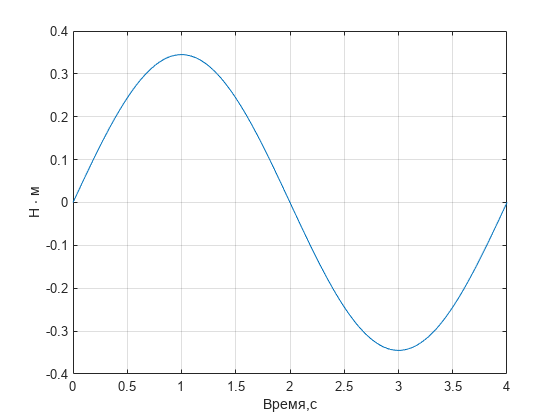


exportgraphics(gcf, 'sin_moment.pdf', 'ContentType', 'vector', 'BackgroundColor', 'white');

Линейный алгоритм

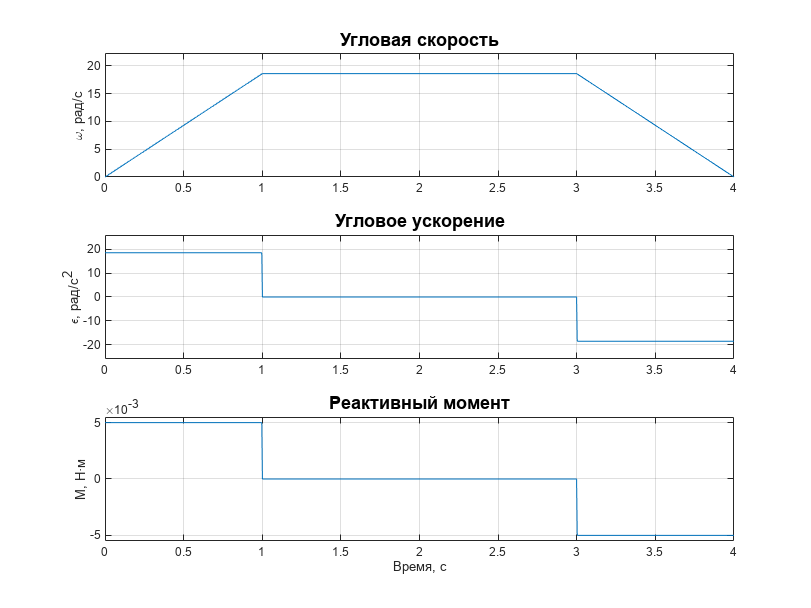

clear
clc
% Параметры
phi_total_deg = 319.5*10;                      % полный угол в градусах
phi_total = deg2rad(phi_total_deg);     % перевод в радианы
T = 4;                                   % общее время
t1 = 1; t2 = 2; t3 = 1;                  % интервалы разгона, плато, торможения

omega_max = phi_total / 3;              % максимальная угловая скорость (см. вывод ранее)
eps_val = omega_max / t1;               % постоянное угловое ускорение

% Временная ось
t = linspace(0, 4, 1000);

% Выделение интервалов
omega = zeros(size(t));
phi = zeros(size(t));
eps = zeros(size(t));

for i = 1:length(t)
    ti = t(i);
    if ti <= t1
        % Разгон
        omega(i) = eps_val * ti;
        phi(i) = 0.5 * eps_val * ti^2;
        eps(i) = eps_val;
    elseif ti <= t1 + t2
        % Плато
        omega(i) = omega_max;
        phi(i) = 0.5 * omega_max * t1 + omega_max * (ti - t1);
        eps(i) = 0;
    else
        % Торможение
        dt = ti - (t1 + t2);
        omega(i) = omega_max - eps_val * dt;
        phi(i) = 0.5 * omega_max * t1 + omega_max * t2 + omega_max * dt - 0.5 * eps_val * dt^2;
        eps(i) = -eps_val;
    end
end

% Построение графиков
figure('Units','normalized','Position',[0.1 0.5 0.6 0.8]);



subplot(3,1,1);
plot(t, omega);
grid on;
ylabel('\omega, рад/с');
xlim([0 4]);
ylim([0 max(omega) * 1.2])
title('Угловая скорость', "FontSize", 14);

subplot(3,1,2);
plot(t, eps);
grid on;
ylabel('\epsilon, рад/с^2');
ylim([min(eps)*1.4 max(eps)*1.4])
title('Угловое ускорение', "FontSize", 14);

j = 2.69*10^-4;
M = eps*j;
subplot(3,1,3);
plot(t, M);
grid on;
xlabel('Время, с');
ylabel('M, Н·м');
xlim([0 4]);
ylim([-max(M)*1.1 max(M)*1.1])
title('Реактивный момент', "FontSize", 14);

% Сохранить график
exportgraphics(gcf, 'line_profile.pdf', 'ContentType', 'vector', 'BackgroundColor', 'white');
exportgraphics(gcf, 'line_profile.png', 'ContentType', 'vector', 'BackgroundColor', 'white');


%jerk = gradient(eps);
%plot(t, jerk);


Экспонециальный алгоритм

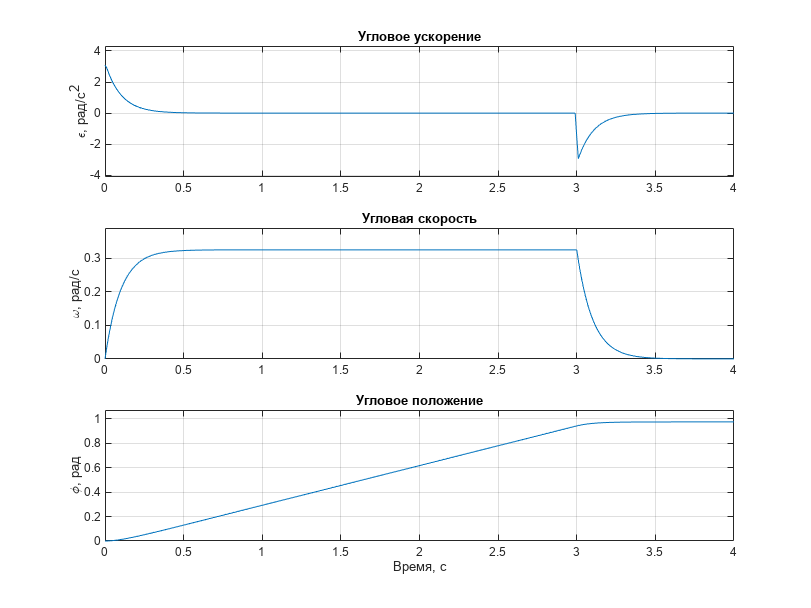

clear 
clc
% Параметры движения
Omega_min = deg2rad(0.02);    % Минимальная скорость (град/с)
Omega_max = deg2rad(18.58);     % Максимальная скорость (град/с)
k = 10;               % Коэффициент экспоненциальной кривой
t_r = 1.0;           % Время разгона (сек)
t_c = 2.0;           % Время равномерного движения (сек)
T = 2*t_r + t_c;     % Общее время

% Временные интервалы
dt = 0.01;
t = 0:dt:T;

% Инициализация массива скоростей
Omega = zeros(size(t));

% Расчёт по кусочно-заданной функции
for i = 1:length(t)
    if t(i) < t_r
        % Разгон
        Omega(i) = Omega_min + (Omega_max - Omega_min) * (1 - exp(-k * t(i)));
    elseif t(i) < t_r + t_c
        % Равномерное движение
        Omega(i) = Omega_max;
    else
        % Торможение
        Omega(i) = Omega_min + (Omega_max - Omega_min) * exp(-k * (t(i) - t_r - t_c));
    end
end

% Построение графика
%figure;
%plot(t, Omega);
%xlabel('Время t (с)');
%ylabel('Угловая скорость \omega(t) (\circ/с)');
%title('Профиль угловой скорости шагового двигателя');
%grid on;
%xline(t_r, '--k', 'Конец разгона');
%xline(t_r + t_c, '--k', 'Начало торможения');
%legend('\Omega(t)', 'Location', 'Best');

acceleration = gradient(Omega, dt); 

angle = cumtrapz(t, Omega);  % ∫Ω(t) dt

jerk = gradient(acceleration, dt);


subplot(3,1,1);
plot(t, acceleration);
grid on;
ylabel('\epsilon, рад/с^2');
xlim([0 4]);
ylim([min(acceleration)*1.4 max(acceleration)*1.4])
title('Угловое ускорение');

subplot(3,1,2);
plot(t, Omega);
grid on;
ylabel('\omega, рад/с');
xlim([0 4]);
ylim([0 max(Omega) * 1.2])
title('Угловая скорость');

subplot(3,1,3);
plot(t, angle);
grid on;
xlabel('Время, с');
ylabel('\phi, рад');
xlim([0 4]);
ylim([0 max(angle)*1.1])
title('Угловое положение');

exportgraphics(gcf, 'exp_profile.pdf', 'ContentType', 'vector', 'BackgroundColor', 'white');

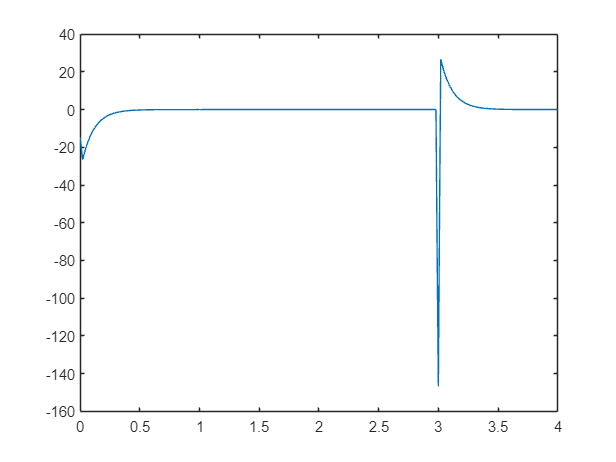


figure
plot(t, jerk)